# **Concentration Calculation**

**Concentration Calculation calculates the concentration of the APT Dataset and visualises the data. You can plot a bar or a pie chart based on the concentration or counts. **

For the calculation of the concentration, a decomposed pos file with atoms/ions is needed and the colorScheme.

## Calculate the concentration, count and variance of each ion species

The user can calculate the concentration using the detector Efficiency, an excludeList containing all elements that the user don't want to contribute to the concentration. For example, the user can exclude Ga ions that may be implemented during FIB preparation into the atom probe tip.  volumeName is the Name of the volume

detEff = 0.37; % detector efficiency of your Atom Probe (CAMECA LEAP 4000 XHR)
excludeList = {'Ga', 'unranged', 'unkownGaH'}; % List of ions that don't contribute to the concentration calculation 
volumeName = 'VolumeAll'; % name of the volume
conc = posCalculateConcentrationSimple(pos, detEff, excludeList,volumeName) % calculates the count, concentration and variance

conc = 3×13 table
     volume      distance     type        format            H             C             N             O             Fe            F          Ga     unkownGaH     unranged 
    _________    ________    ______    _____________    __________    __________    __________    __________    __________    __________    ____    _________    __________

    VolumeAll       0        atomic    count                  5952         15007          4364          2887    1.0641e+07           961    1965      2445       1.7064e+06
    VolumeAll       0  

## Plot the concentration or count as a bar or pie chart 

The user can plot the concentration or count as a bar or pie chart 

ColorScheme is a variable input. If it is not parsed all bars appear in one color. The user can also change the axis of the plot to a logarithmic scale for bar plots.

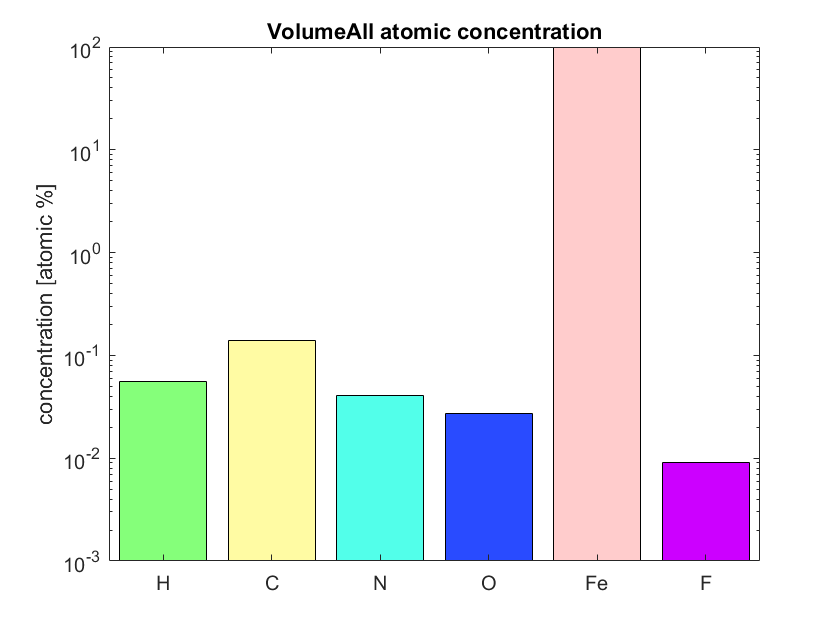

plotType = 'bar';
format = 'concentration';
[p, ax, f] = concentrationPlot(conc([conc.format==format], :),excludeList, plotType, colorScheme);
ax.YScale = 'log'; % If you prefer a logarithmic scale for a bar plot